# Linearisation of benchmark mechatronic systems

This livescript is a manual in support of the app ***linearisation_Benchmark_control101.mlapp***.   This is a virtual laboratory to help students engage with the concepts of linearisation of systems and the associated behaviours and the impact on computer controlled systems.  Two benchmark nonlinear systems will be considered. Comparisons of behaviour between the linearised and non-linear systems are given.  The manual here also provides detailed code snippets so that students can repeat the process on models of their own, whereas the app is restricted to the examples coded within it.

$\bullet$ Learn how to deal with real world nonlinear systems on two benchmarks systems such that become able to analyse them in the context of linear time invariant computer-controlled systems and design linear controllers.

$\bullet$ Become familiar with defining nonlinear state-space equations and linearizing them at specific operating points.

$\bullet$ Perform model reduction and obtain second-order transfer functions of higher order systems.

$\bullet$ Compare the behavior of considered nonlinear systems, linearized systems and reduced order linear systems.

Another non-linear example in the toolbox is the conical tank. 

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%  
%        help control101         (opens within the command window)

Source files created by Mehmet Kilic, Yaprak Yalcin, Istanbul Technical University (İTÜ) and also available separately from [https://drive.mathworks.com/sharing/bf093c57-7f71-4380-bec3-c0fa6ffdb8b9](https://drive.mathworks.com/sharing/bf093c57-7f71-4380-bec3-c0fa6ffdb8b9)

Files edited for inclusion in the toolbox by J.A.Rossiter, University of Sheffield    

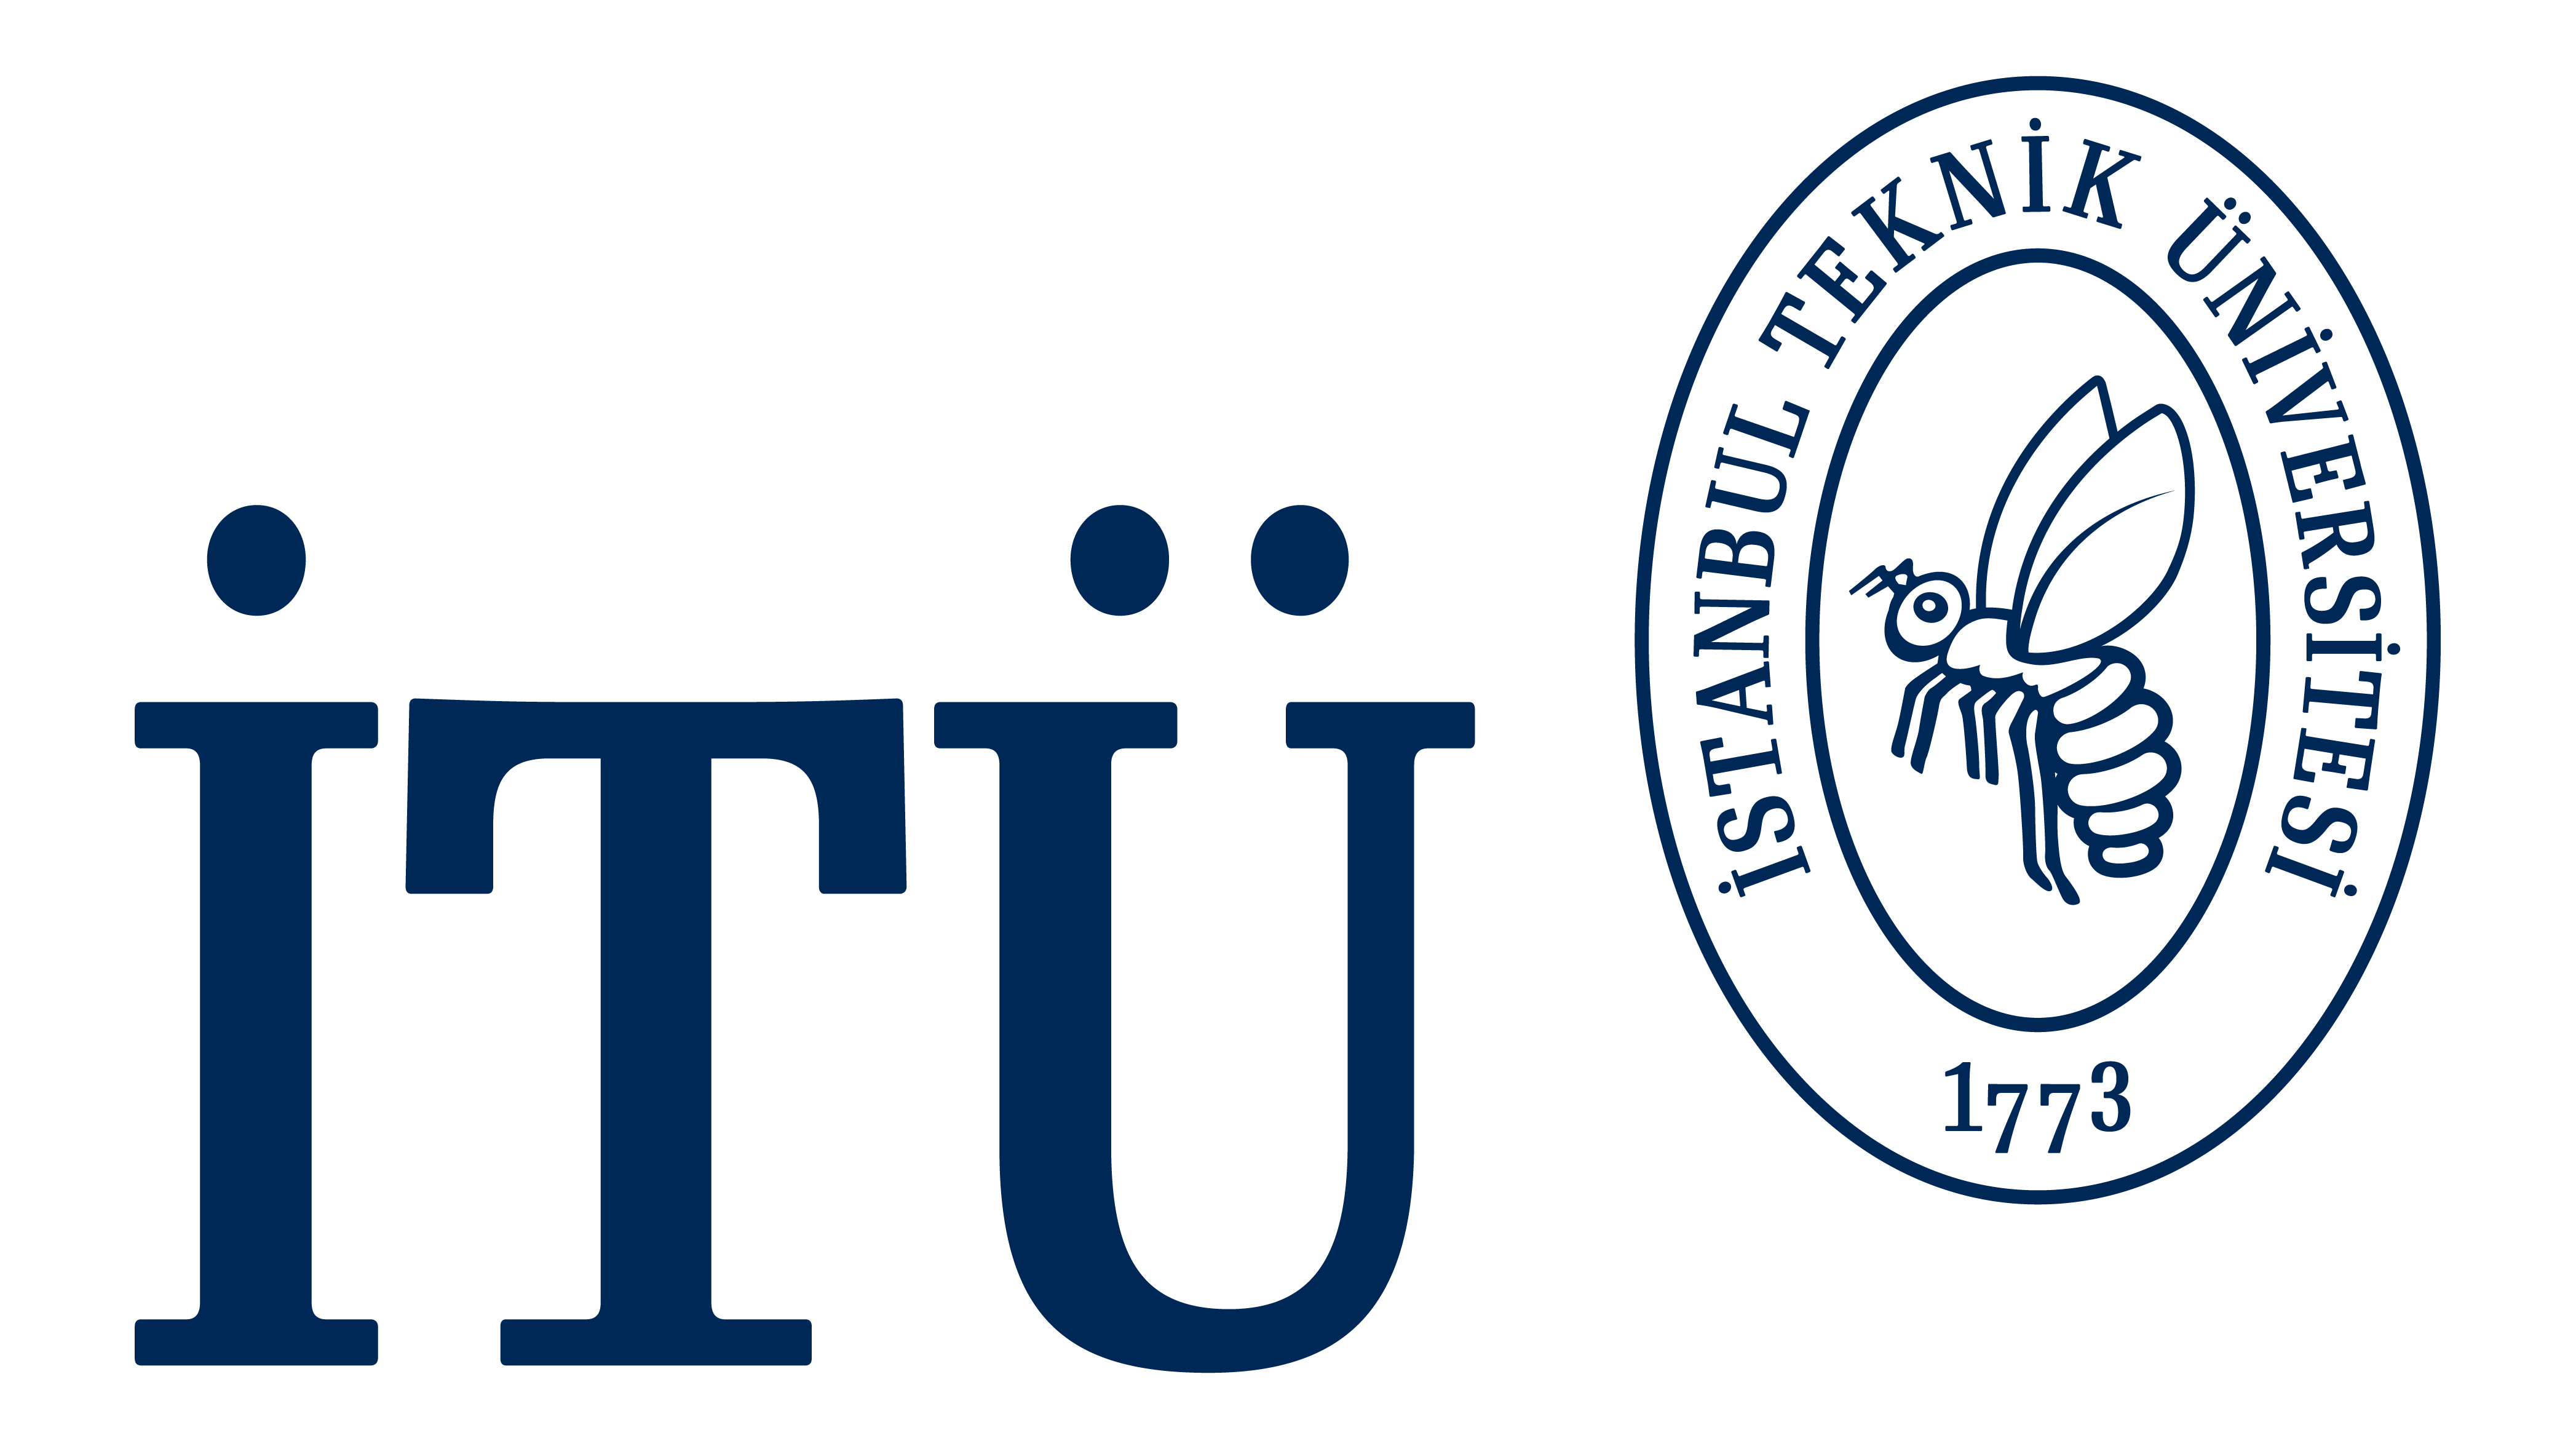                     

## Table of contents

- Introduction

- Fan and plate system

- 1-DOF Aero VTOL System

- The virtual laboratory on linearisation

- Establishing Computer Controlled Systems

## 1 Introduction

In order to better understand the main concepts related with the Computer Controlled Systems, two benchmark nonlinear systems will be considered. Even if the considered systems are nonlinear, the topics will be covered in terms of linear time invariant systems via linearizing the considered nonlinear systems at some operating points. 

## 2 Fan and Plate System

Figure 1 depicts the general structure of a fan and plate system.

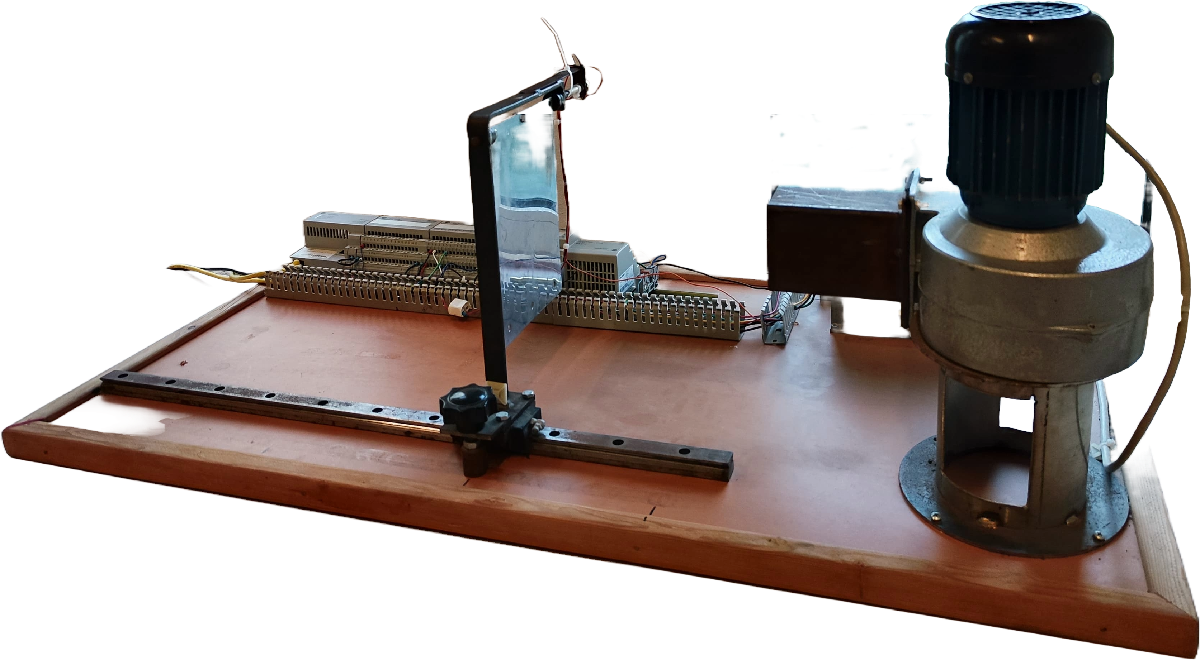

Figure 1. Fan and Plate System

### 2.1 System modelling and linearisation

The following nonlinear equations for the system are assumed.The system states are given respectively as: actuator current (A), actuator fan speed (rad/s), plate angular speed (rad/s) and plate angular position (rad). The input $u\left(t\right)$ is a voltage.


$$x\left(t\right)={\left\lbrack \begin{array}{cccc}
x_1 \left(t\right) & x_2 \left(t\right) & x_3 \left(t\right) & x_4 \left(t\right)
\end{array}\right\rbrack }^T ={\left\lbrack \begin{array}{cccc}
i_m \left(t\right) & \omega_m \left(t\right) & \omega_p \left(t\right) & \theta_p \left(t\right)
\end{array}\right\rbrack }^T$$


$u\left(t\right)=V_i \left(t\right)$, $d\left(t\right)=\tau_d \left(t\right)$


$${\dot{x} }_1 \left(t\right)={\dot{i} }_m \left(t\right)=f_1 \left(x,u\right)=-\frac{R_m }{L_m }x_1 \left(t\right)-\frac{K_b }{L_m }x_2 \left(t\right)+\frac{1}{L_m }u\left(t\right)$$



$${\dot{x} }_2 \left(t\right)={\dot{\omega} }_m \left(t\right)=f_2 \left(x,u\right)=\frac{K_t }{J_m }x_1 \left(t\right)-\frac{B_m }{J_m }x_2 \left(t\right)-\frac{K_f }{J_m }x_2^2 \left(t\right)$$



$${\dot{x} }_3 \left(t\right)={\dot{\omega} }_p \left(t\right)=f_3 \left(x,u\right)=-\frac{B_p }{J_p }x_3 \left(t\right)+\frac{\sigma_{\textrm{air}} A_p r^2 l_x }{4J_p }x_2^2 \;\left(t\right)\cos \left(x_4 \left(t\right)\right)-\frac{m_p gl_x }{2J_p }\sin \left(x_4 \left(t\right)\right)+\frac{1}{J_p }d\left(t\right)$$



$${\dot{x} }_4 \left(t\right)={\dot{\theta} }_p \left(t\right)=f_4 \left(x,u\right)=x_3$$

$$\left(t\right)$$


Jacobian linearization for trim point $x_0 ,$ $u_0$,$d_0 \;$is given below.


$$J_f \left(x,u\right)|_{x_{0\;} } =\frac{\partial }{\partial x}f\left(x,u\right)|_{x_{0\;} } =\left\lbrack \begin{array}{cccc}
\frac{\partial }{\partial x_1 }f_1 \left(x,u\right) & \frac{\partial }{\partial x_2 }f_1 \left(x,u\right) & \cdots  & \frac{\partial }{\partial x_5 }f_1 \left(x,u\right)\\
\frac{\partial }{\partial x_1 }f_2 \left(x,u\right) & \frac{\partial }{\partial x_2 }f_2 \left(x,u\right) & \cdots  & \frac{\partial }{\partial x_5 }f_2 \left(x,u\right)\\
\vdots  & \vdots  & \cdots  & \vdots \\
\frac{\partial }{\partial x_1 }f_4 \left(x,u\right) & \frac{\partial }{\partial x_2 }f_4 \left(x,u\right) & \cdots  & \frac{\partial }{\partial x_5 }f_4 \left(x,u\right)
\end{array}\right\rbrack |_{x_{0\;} } =\left\lbrack \begin{array}{cccc}
-\frac{R_m }{L_m } & -\frac{K_b }{L_m } & 0 & 0\\
\frac{K_t }{J_m } & -\frac{\left(B_m +2K_f x_2 \left(0\right)\right)}{J_m } & 0 & 0\\
0 & \frac{\sigma_{\textrm{air}} A_p r^2 l_x }{2J_p }x_2 \left(0\right)\;\cos \left(x_4 \left(0\right)\right) & -\frac{B_p }{J_p } & -\left(\frac{\sigma_{\textrm{air}} A_p r^2 l_x }{4J_p }x_4^2 \left(0\right)\;\sin \left(x_5 \left(0\right)\right)+\frac{m_p gl_x }{2J_p }\cos \left(x_4 \left(0\right)\right)\right)\\
0 & 0 & 1 & 0
\end{array}\right\rbrack$$


$J_u \left(x,u\right)|_{u_{0\;} } =\frac{\partial }{\partial u}f\left(x,u\right)|_{u_{0\;} } =\left\lbrack \begin{array}{c}
\frac{\partial }{\partial u}f_1 \left(x,u\right)\\
\frac{\partial }{\partial u}f_2 \left(x,u\right)\\
\vdots \\
\frac{\partial }{\partial u}f_4 \left(x,u\right)
\end{array}\right\rbrack$$|_{u_{0\;} }$=$\left\lbrack \begin{array}{c}
\frac{1}{L_m }\\
0\\
0\\
0
\end{array}\right\rbrack$,    $J_d \left(x,d\right)|_{d_{0\;} } =\frac{\partial }{\partial d}f\left(x,d\right)|_{d_{0\;} } =\left\lbrack \begin{array}{c}
\frac{\partial }{\partial d}f_1 \left(x,d\right)\\
\frac{\partial }{\partial d}f_2 \left(x,d\right)\\
\vdots \\
\frac{\partial }{\partial d}f_4 \left(x,d\right)
\end{array}\right\rbrack$$|_{d_{0\;} }$=$\left\lbrack \begin{array}{c}
0\\
0\\
\frac{1}{J_p }\\
0
\end{array}\right\rbrack$

The linearized system equations in state space form at operating point $x_O$ are as follows:


$$\begin{array}{l}
\dot{x} \left(t\right)=\left\lbrack \begin{array}{c}
{\dot{x} }_1 \left(t\right)\\
{\dot{x} }_2 \left(t\right)\\
{\dot{x} }_3 \left(t\right)\\
{\dot{x} }_4 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\dot{i} }_m \left(t\right)\\
{\dot{\omega} }_m \left(t\right)\\
{\dot{\omega} }_p \left(t\right)\\
{\dot{\theta} }_p \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
-\frac{R_m }{L_m } & -\frac{K_b }{L_m } & 0 & 0\\
\frac{K_t }{J_m } & -\frac{\left(B_m +2K_f x_2 \left(0\right)\right)}{J_m } & 0 & 0\\
0 & \frac{\sigma_{\textrm{air}} A_p r^2 l_x }{2J_p }x_2 \left(0\right)\;\cos \left(x_5 \left(0\right)\right) & -\frac{B_p }{J_p } & -\left(\frac{\sigma_{\textrm{air}} A_p r^2 l_x }{4J_p }x_2^2 \left(0\right)\;\sin \left(x_5 \left(0\right)\right)+\frac{m_p gl_x }{2J_p }\cos \left(x_5 \left(0\right)\right)\right)\\
0 & 0 & 1 & 0
\end{array}\right\rbrack x\left(t\right)+\left\lbrack \begin{array}{c}
\frac{1}{L_m }\\
0\\
0\\
0
\end{array}\right\rbrack u\left(t\right)+\left\lbrack \begin{array}{c}
0\\
0\\
\frac{1}{J_p }\\
0
\end{array}\right\rbrack d\left(t\right)\\
y\left(t\right)=\left\lbrack \begin{array}{ccccc}
0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack x\left(t\right)
\end{array}$$


### 2.2 Simulation illustration

The following code shows how to perform the linearisation using MATLAB tools and then to do a simulation.  Also, for simplicity of analysis, a model reduction to a second order system is used before obtaining the corresponding transfer function.

**Define the model parameters**

disp('Fan and plate results below')

Fan and plate results below


% Configuration and format
clear all;
close all;
clc;

format longg;

% Parameter set  (Loads these values directly by running FanAndPlate_Data.m) 
% The simulink file runs this automatically so would need to change the
% values within that file
FanAndPlate_Data_control101
%  Short cut files to replace modelling code above and below
%sys=FanAndPlate_model_control101(x0);

**Linearisation**

Linearisation needs symbolic variables and the jacobian function. 

% Define symbolic variables
syms x1 x2 x3 x4 u d Rm Lm Kb Kt Jm Bm Kpl rho r Ap lx Bp Jp mp g real
x = [ x1; x2; x3; x4 ];

% Define the nonlinear state equations
f = [-Rm/Lm*x1 - Kb/Lm*x2 + u/Lm ;
      Kt/Jm*x1 - Bm/Jm*x2 - Kpl/Jm*x2^2 ;
      -Bp/Jp*x3+((rho*Ap*(r^2)*lx)/(4*Jp))*(x2^2)*cos(x4)-mp*g*lx/(2*Jp)*sin(x4)+d/Jp ;
      x3];  % Example: Simple nonlinear system
h = x4;        % Example: Output equations

% Compute the Jacobian matrices
Aj= jacobian(f, x);  % Jacobian of f with respect to x
Bj = jacobian(f, u);  % Jacobian of f with respect to u
Cj = jacobian(h, x);  % Jacobian of h with respect to x
Dj= jacobian(h, u);  % Jacobian of h with respect to u

**Substitution of parameter values in to the symbolic expressions**

The linearisation is done for a 500 rpm actuator fan speed (this must be converted to rad/s) and with the other states at zero.

% Define the operating point
speed= 2*pi*500/60;
x0 = [ 0; speed; 0; 0];

% Substitute the system parameters into the Jacobians
A= subs(   Aj, ...
        [ Rm; Lm; Kb; Kt; Jm; Bm; Kpl; rho; r; Ap; lx; Bp; Jp; mp; g ], ...
        [ Rm_P; Lm_P; Kb_P; Kt_P; Jm_P; Bm_P; Kpl_P; rho_P; r_P; Ap_P; lx_P; Bp_P; Jp_P; mp_P; g_P ]);
B = subs(   Bj, ...
        [ Rm; Lm; Kb; Kt; Jm; Bm; Kpl; rho; r; Ap; lx; Bp; Jp; mp; g ], ...
        [ Rm_P; Lm_P; Kb_P; Kt_P; Jm_P; Bm_P; Kpl_P; rho_P; r_P; Ap_P; lx_P; Bp_P; Jp_P; mp_P; g_P ]);
C=Cj;
D=Dj;
% Substitute the operating point into the Jacobians
A_lin = subs(A, x, x0 );
B_lin = subs(B, x, x0);
C_lin = subs(C, x, x0);
D_lin = subs(D, x, x0);

% Convert symbolic matrices to numeric values
A_lin = double(A_lin);
B_lin = double(B_lin);
C_lin = double(C_lin);
D_lin = double(D_lin);

% % Display the linearized system matrices
disp('A_lin matrix:');

A_lin matrix:


disp(A_lin);

         -1723.16384180791         -4350.28248587571                         0                         0
           1436.5671641791         -462.033125223246                         0                         0
                         0        0.0136413110857554         -5.33320895522388         -4.94160447761194
                         0                         0                         1                         0



disp('B_lin matrix:');

B_lin matrix:


disp(B_lin);

          56497.1751412429
                         0
                         0
                         0



disp('C_lin matrix:');

C_lin matrix:


disp(C_lin);

     0     0     0     1



disp('D_lin matrix:');

D_lin matrix:


disp(D_lin);

     0



**Model reduction**

Next we use the tool balred to reduce the system from 4th order to 2nd order. This can be justified where you are confident or have evidence that such a reduction is a sensible approximation (not discussed here). As the system has a single input and output, it can also be expressed in  transfer function form where this is convenient.

% Create the state-space system
sys = ss(A_lin, B_lin, C_lin, D_lin);
% Reduce the system to a second-order model
order_reduced = 2;
sys_reduced = balred(sys, order_reduced);

% Extract the reduced system matrices
[A_reduced, B_reduced, C_reduced, D_reduced] = ssdata(sys_reduced);

% Convert state-space to transfer function
[num, den] = ss2tf(A_reduced, B_reduced, C_reduced, D_reduced);

% Optional: Create transfer function model and display
sys_tf = tf(num, den)


sys_tf =
 
  -7.041e-09 s^2 - 4.874e-05 s + 0.1571
  -------------------------------------
          s^2 + 5.333 s + 4.942
 
Continuous-time transfer function.


**Simulation with linearised and non-linear models**

The simulation is done with an input step change of 12 volts. it can be seen that:

- The reduced order model gives near identical step responses to the higher order linearised model.

- The non-linear response is clearly different.

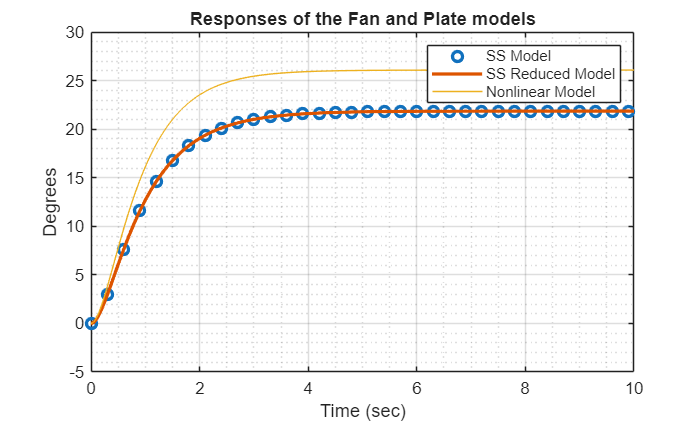

Stoptime=10;
time = linspace(0,Stoptime,1001);
SampleTime=time(2)-time(1);
V=12;
control_input = V*ones(size(time));

% Simulation of linear model and covnersion to degrees
[sys_out ] = step(V*sys, time);
[sys_reduced_out] = step(V*sys_reduced, time);
[sys_tf_out] = step(V*sys_tf, time );
sys_out = rad2deg(sys_out);
sys_reduced_out = rad2deg(sys_reduced_out);
sys_tf_out = rad2deg(sys_tf_out);

% Non-linear simulink model: Define core input choices first
input_data_gl = [time', control_input'];
initialcurrent=x0(1);
fanspeed=x0(2);
initialplatespeed=x0(3);
initialplateangle=x0(4);
sim_output = sim("FanAndPlate_control101.slx");
sim_output.continuous_output.signals.values = rad2deg(sim_output.continuous_output.signals.values);

figure;
plot( time(1:30:end), sys_out(1:30:end),'o', 'LineWidth', 2 )
hold on;
grid on;
grid minor;
plot( time, sys_reduced_out, 'LineWidth', 2 )
%plot( time, sys_tf_out, 'LineWidth', 2 )
plot( sim_output.continuous_output.time, sim_output.continuous_output.signals.values);
legend( "SS Model", "SS Reduced Model", "Nonlinear Model" );
title('Responses of the Fan and Plate models')
ylabel('Degrees')
xlabel('Time (sec)')

### 2.3 Exercise for students

Obtain the linearized state-space equations at 500 rpm actuator fan speed and $\frac{\pi }{3}\textrm{rad}$ plate angular position. Perform model reduction to a second order system and obtain the corresponding transfer function. Then, obtain the step response of orginal system and the reduced system you obtain in this exercise. Compare the behaviors obtained in Example 1.

**Note**: In essence this will use identical code to above but with a change to the definition of variable x0 so there is no need to duplicate all the code. Just change the relevant line and press run section. The only part that needs more coding is saving your responses and the comparison of the behaviour plots.

In order to investigate, the behavior of linearised benchmark systems on diferrent operating points more easily, please use the app discussed in section 3 below.

## 3 1-DOF Aero VTOL System

Figure 2 depicts the general structure of the 1-DOF Aero VTOL system.

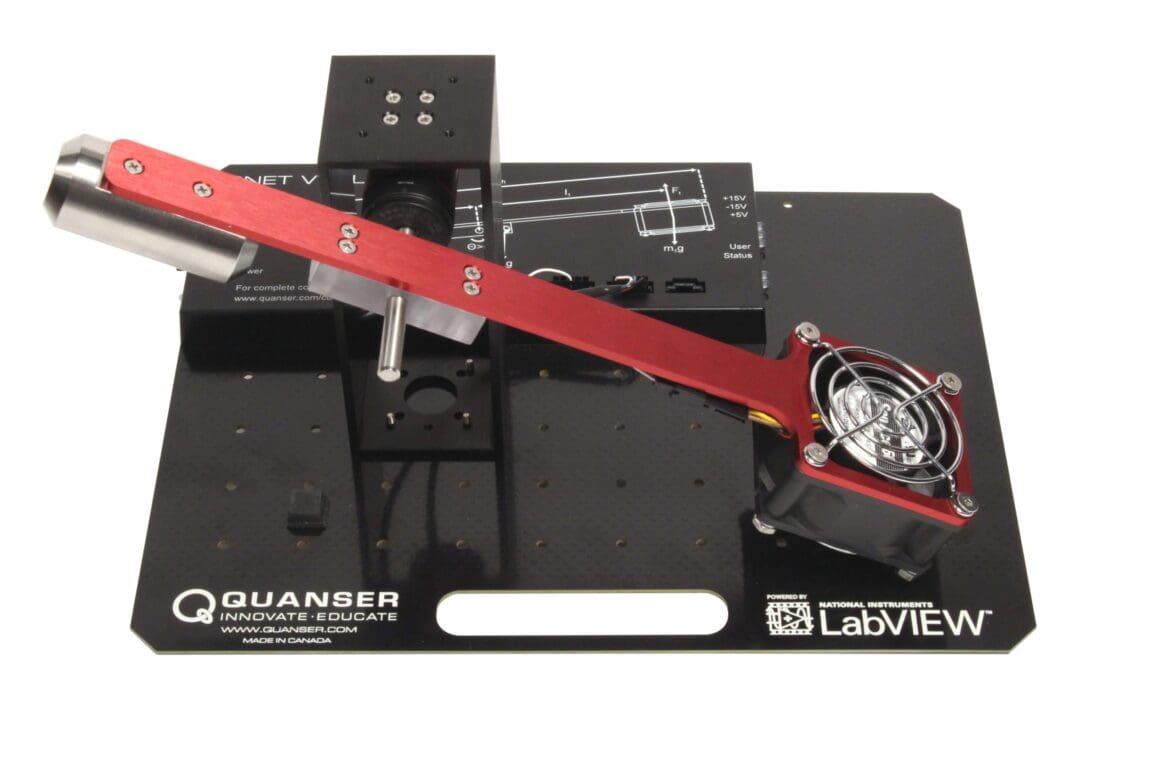

Figure 2. 1-DOF Aero VTOL System

### 3.1 Modelling equations and linearisation

In the MATLAB apps and simulations, the following nonlinear equations for the system are assumed.The system states are given respectively as: actuator current (A), actuator propeller speed (rad/s), pivot angular speed (rad/s) and pivot angular position (rad) and the input $u\left(t\right)$ is a voltage.


$$x\left(t\right)={\left\lbrack \begin{array}{cccc}
x_1 \left(t\right) & x_2 \left(t\right) & x_3 \left(t\right) & x_4 \left(t\right)
\end{array}\right\rbrack }^T ={\left\lbrack \begin{array}{cccc}
i_m \left(t\right) & \omega_m \left(t\right) & \omega_l \left(t\right) & \theta_l \left(t\right)
\end{array}\right\rbrack }^T$$



$$u\left(t\right)=V_i \left(t\right)$$



$$d\left(t\right)=\tau_d \left(t\right)$$



$${\dot{x} }_1 \left(t\right)={\dot{i} }_m \left(t\right)=f_1 \left(x,u\right)=-\frac{R_m }{L_m }x_1 \left(t\right)-\frac{K_b }{L_m }x_2 \left(t\right)+\frac{1}{L_m }u\left(t\right)$$



$${\dot{x} }_2 \left(t\right)={\dot{\omega} }_m \left(t\right)=f_2 \left(x,u\right)=\frac{K_t }{J_m }x_1 \left(t\right)-\frac{B_m }{J_m }x_2 \left(t\right)-\frac{K_f }{J_m }x_2^2 \left(t\right)$$



$${\dot{x} }_3 \left(t\right)={\dot{\omega} }_p \left(t\right)=f_3 \left(x,u\right)=\frac{K_f l_1 }{J_l }x_2^2 \;\left(t\right)-\frac{B_l }{J_l }x_3 \left(t\right)+\left(\frac{m_2 gl_2 }{J_l }-\frac{m_1 gl_1 }{J_l }-\frac{m_3 gl_3 }{J_l }\right)\cos \left(x_4 \left(t\right)\right)+\frac{1}{J_l }d\left(t\right)$$



$${\dot{x} }_4 \left(t\right)={\dot{\theta} }_p \left(t\right)=f_4 \left(x,u\right)=x_3$$

$$\left(t\right)$$


Jacobian Linearization for trim point $x_0 ,$ $u_0$,$d_0 \;$is given below.


$$J_f \left(x,u\right)|_{x_{0\;} } =\frac{\partial }{\partial x}f\left(x,u\right)|_{x_{0\;} } =\left\lbrack \begin{array}{cccc}
\frac{\partial }{\partial x_1 }f_1 \left(x,u\right) & \frac{\partial }{\partial x_2 }f_1 \left(x,u\right) & \cdots  & \frac{\partial }{\partial x_5 }f_1 \left(x,u\right)\\
\frac{\partial }{\partial x_1 }f_2 \left(x,u\right) & \frac{\partial }{\partial x_2 }f_2 \left(x,u\right) & \cdots  & \frac{\partial }{\partial x_5 }f_2 \left(x,u\right)\\
\vdots  & \vdots  & \cdots  & \vdots \\
\frac{\partial }{\partial x_1 }f_4 \left(x,u\right) & \frac{\partial }{\partial x_2 }f_4 \left(x,u\right) & \cdots  & \frac{\partial }{\partial x_5 }f_4 \left(x,u\right)
\end{array}\right\rbrack |_{x_{0\;} } =\left\lbrack \begin{array}{cccc}
-\frac{R_m }{L_m } & -\frac{K_b }{L_m } & 0 & 0\\
\frac{K_t }{J_m } & -\frac{\left(B_m +2K_f x_2 \left(0\right)\right)}{J_m } & 0 & 0\\
0 & \frac{2K_f l_1 }{J_l }x_2 \left(0\right) & -\frac{B_l }{J_l } & -\left(\frac{m_2 gl_2 }{J_l }-\frac{m_1 gl_1 }{J_l }-\frac{m_3 gl_3 }{J_l }\right)\sin \left(x_4 \left(0\right)\right)\\
0 & 0 & 1 & 0
\end{array}\right\rbrack$$


$J_u \left(x,u\right)|_{u_{0\;} } =\frac{\partial }{\partial u}f\left(x,u\right)|_{u_{0\;} } =\left\lbrack \begin{array}{c}
\frac{\partial }{\partial u}f_1 \left(x,u\right)\\
\frac{\partial }{\partial u}f_2 \left(x,u\right)\\
\vdots \\
\frac{\partial }{\partial u}f_4 \left(x,u\right)
\end{array}\right\rbrack$$|_{u_{0\;} }$=$\left\lbrack \begin{array}{c}
\frac{1}{L_m }\\
0\\
0\\
0
\end{array}\right\rbrack$

$J_d \left(x,d\right)|_{d_{0\;} } =\frac{\partial }{\partial d}f\left(x,d\right)|_{d_{0\;} } =\left\lbrack \begin{array}{c}
\frac{\partial }{\partial d}f_1 \left(x,d\right)\\
\frac{\partial }{\partial d}f_2 \left(x,d\right)\\
\vdots \\
\frac{\partial }{\partial d}f_4 \left(x,d\right)
\end{array}\right\rbrack$$|_{d_{0\;} }$=$\left\lbrack \begin{array}{c}
0\\
0\\
\frac{1}{J_l }\\
0
\end{array}\right\rbrack$

Linearized system equations at operating point $x_O$ are as follows:


$$\begin{array}{l}
\dot{x} \left(t\right)=\left\lbrack \begin{array}{c}
{\dot{x} }_1 \left(t\right)\\
{\dot{x} }_2 \left(t\right)\\
{\dot{x} }_3 \left(t\right)\\
{\dot{x} }_4 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\dot{i} }_m \left(t\right)\\
{\dot{\omega} }_m \left(t\right)\\
{\dot{\omega} }_p \left(t\right)\\
{\dot{\theta} }_p \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
-\frac{R_m }{L_m } & -\frac{K_b }{L_m } & 0 & 0\\
\frac{K_t }{J_m } & -\frac{\left(B_m +2K_f x_2 \left(0\right)\right)}{J_m } & 0 & 0\\
0 & \frac{2K_f l_1 }{J_l }x_2 \left(0\right) & -\frac{B_l }{J_l } & -\left(\frac{m_2 gl_2 }{J_l }-\frac{m_1 gl_1 }{J_l }-\frac{m_3 gl_3 }{J_l }\right)\sin \left(x_4 \left(0\right)\right)\\
0 & 0 & 1 & 0
\end{array}\right\rbrack x\left(t\right)+\left\lbrack \begin{array}{c}
\frac{1}{L_m }\\
0\\
0\\
0
\end{array}\right\rbrack u\left(t\right)+\left\lbrack \begin{array}{c}
0\\
0\\
\frac{1}{J_l }\\
0
\end{array}\right\rbrack d\left(t\right)\\
y\left(t\right)=\left\lbrack \begin{array}{ccccc}
0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack x\left(t\right)
\end{array}$$


### 3.2 Simulation illustration and code

The following example obtains the linearised state-space equations for the VTOL using the modelling equations above.

**Define parameters and do a symbolic linearisation**

disp('************************************************')

************************************************


disp('')
disp('VTOL results below')

VTOL results below


% Configuration and format
clear all;
close all;
clc;

format longg;

% Parameter set this loads by running the file OneDofAeroVTOL_Data_control101.m
% The simulink file runs this automatically
OneDofAeroVTOL_Data_control101
% sys=OneDofAeroVTOL_model_control101(x0);  % Duplicates mdoelling code below
                 

% Define symbolic variables
syms x1 x2 x3 x4 u d Rm Lm Kb Kt Jm Bm Kpl Kf l1 l2 l3 Bl Jl m1 m2 m3 g real
x = [ x1; x2; x3; x4 ];

% Define the nonlinear state equations
f = [-Rm/Lm*x1 - Kb/Lm*x2 + u/Lm ;
      Kt/Jm*x1 - Bm/Jm*x2 - Kpl/Jm*x2^2 ;
      (Kf*l1/Jl)*x2^2-(Bl/Jl)*x3+((m2*g*l2-m1*g*l1-m3*g*l3)/Jl)*cos(x4) ;
      x3];  % Example: Simple nonlinear system
h = x4;        % Example: Output equations

% Compute the Jacobian matrices
Aj= jacobian(f, x);  % Jacobian of f with respect to x
Bj= jacobian(f, u);  % Jacobian of f with respect to u
Cj = jacobian(h, x);  % Jacobian of h with respect to x
Dj= jacobian(h, u);  % Jacobian of h with respect to u

**Find numerical values for linearised model at a given operating point**

Perform the linearisation at 50 rpm actuator propeller speed and perform model reduction of the system to a second order system and obtain corresponding transfer function. The other states are initialised at zero.

speed = 2*pi*50/60;  % speed in rad/s
x0 = [ 0; speed; 0; 0];  % Example operating point for x
u0 = 0;
d0 = 0;

% Substitute the system parameters into the Jacobians
A = subs(   Aj, ...
        [ Rm; Lm; Kb; Kt; Jm; Bm; Kpl; Kf; l1; l2; l3; Bl; Jl; m1; m2; m3; g ], ...
        [ Rm_P; Lm_P; Kb_P; Kt_P; Jm_P; Bm_P; Kpl_P; Kf_P; l1_P; l2_P; l3_P; Bl_P; Jl_P; m1_P; m2_P; m3_P; g_P ])

$$A = \left(\begin{array}{cccc} -\frac{420000}{269} & -\frac{2885}{269} & 0 & 0\\ \frac{1330471416316301410304}{4242751136953196875} & -\frac{2305843009213693952\,x_{2}}{21213755684765984375}-\frac{4611686018427387904}{848550227390639375} & 0 & 0\\ 0 & \frac{78\,x_{2}}{2125} & -\frac{200}{17} & -\frac{173637\,\sin\left(x_{4}\right)}{10625}\\ 0 & 0 & 1 & 0 \end{array}\right)$$

B = subs(   Bj, ...
        [ Rm; Lm; Kb; Kt; Jm; Bm; Kpl; Kf; l1; l2; l3; Bl; Jl; m1; m2; m3; g ], ...
        [ Rm_P; Lm_P; Kb_P; Kt_P; Jm_P; Bm_P; Kpl_P; Kf_P; l1_P; l2_P; l3_P; Bl_P; Jl_P; m1_P; m2_P; m3_P; g_P ])

$$B = \left(\begin{array}{c} \frac{50000}{269}\\ 0\\ 0\\ 0 \end{array}\right)$$

C=Cj

$$C = \left(\begin{array}{cccc} 0 & 0 & 0 & 1 \end{array}\right)$$

D=Dj

$$D = 0$$


% Substitute the operating point into the Jacobians
A_lin = subs(A, x, x0 );
B_lin = subs(B, x, x0);
C_lin = subs(C, x, x0);
D_lin = subs(D, x, x0);

% Convert symbolic matrices to numeric values
A_lin = double(A_lin);
B_lin = double(B_lin);
C_lin = double(C_lin);
D_lin = double(D_lin);

% % Display the linearized system matrices
disp('A_lin matrix:');

A_lin matrix:


disp(A_lin);

         -1561.33828996283          -10.724907063197                         0                         0
          313.586956521739         -6.00391171260685                         0                         0
                         0         0.192191550572552         -11.7647058823529                         0
                         0                         0                         1                         0



disp('B_lin matrix:');

B_lin matrix:


disp(B_lin);

          185.873605947955
                         0
                         0
                         0



disp('C_lin matrix:');

C_lin matrix:


disp(C_lin);

     0     0     0     1



disp('D_lin matrix:');

D_lin matrix:


disp(D_lin);

     0



**State space and transfer function models (original and reduced order)**

% Create the state-space system
sys = ss(A_lin, B_lin, C_lin, D_lin);
% Reduce the system to a second-order model
order_reduced = 2;
sys_reduced = balred(sys, order_reduced);
% Determine the reduced system state space matrices
[A_reduced, B_reduced, C_reduced, D_reduced] = ssdata(sys_reduced);

% Convert state-space to transfer function
[num, den] = ss2tf(A_reduced, B_reduced, C_reduced, D_reduced);
% Create transfer function model and display
sys_tf = tf(num, den)


sys_tf =
 
  0.0008675 s^2 - 0.02756 s + 0.4918
  ----------------------------------
            s^2 + 6.578 s
 
Continuous-time transfer function.


**Simulation and plotting**

Compute and plot the responses for linearised and non-linearised models for a step change of 12 volts. The output is converted to degrees for the plots.

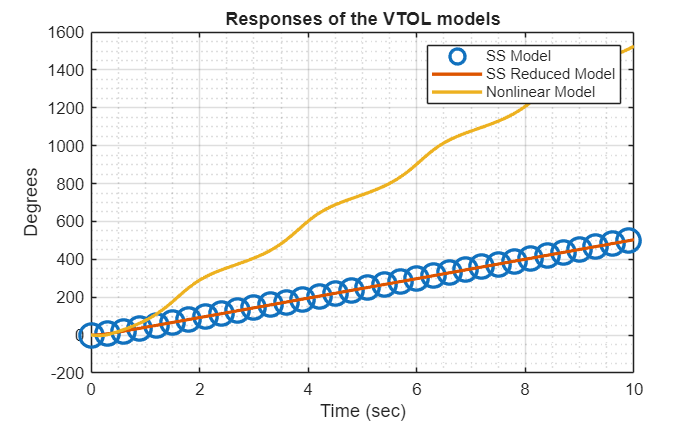


% Simulation and plotting
Stoptime=10;
time = linspace(0,Stoptime,1001);
SampleTime=time(2)-time(1);
V=12;


% Linearised models
[sys_out] = step(V*sys, time);
[sys_reduced_out ] = step(V*sys_reduced, time);
[sys_tf_out] = step(V*sys_tf, time );
sys_out = rad2deg(sys_out);
sys_reduced_out = rad2deg(sys_reduced_out);
sys_tf_out = rad2deg(sys_tf_out);

% Non-linear simulink model
control_input = V*ones(size(time));
initialcurrent=x0(1);
fanspeed=x0(2);
initialplatespeed=x0(3);
initialplateangle=x0(4);

input_data_gl = [time', control_input'];
sim_output = sim("OneDofAeroVTOL_control101.slx");
sim_output.continuous_output.signals.values = rad2deg(sim_output.continuous_output.signals.values);

figure;
plot( time(1:30:end), sys_out(1:30:end),'o', 'LineWidth', 2 )
hold on;
grid on;
grid minor;
plot( time, sys_reduced_out, 'LineWidth', 2 )
%plot( time, sys_tf_out, 'LineWidth', 2 )
plot( sim_output.continuous_output.time, sim_output.continuous_output.signals.values);
legend( "SS Model", "SS Reduced Model", "Nonlinear Model" );
title('Responses of the VTOL models')
ylabel('Degrees')
xlabel('Time (sec)')

### 3.3 Exercise for students

Obtain the linearized state-space equations at  50rpm actuator propeller speed  and $\frac{\pi }{3}\textrm{rad}$ pivot angular position. Perform model reduction to second order system and obtain the corresponding transfer function. Then, obtain the step response of orginal system and the reduced system you obtain in this exercise. Compare to the behaviors obtained above.  You can explore different initial conditions by simply changing xo in the code above and then using *run section*.

In order to investigate, the behavior of linearised benchmark systems on diferrent operating points more easily, please use the app discussed in section 3 below.

## 4 The virtual laboratory on linearisation

The virtual laboratory ***linearisation_Benchmark_control101 .mlapp*** allows users to quickly assess the impact of linearisation. Is the lienarised model a good fit or not? Users can also overlay responses for a variety of initial conditions and settings to study the impact. An illustration is given in Figure 3 below.

Users may note that the initial conditions for current and fan speed do not impact much on behavour of the non-lienar model as their imapct is quickly dominated by the new voltage. However, they do impact on the linearised model definition.

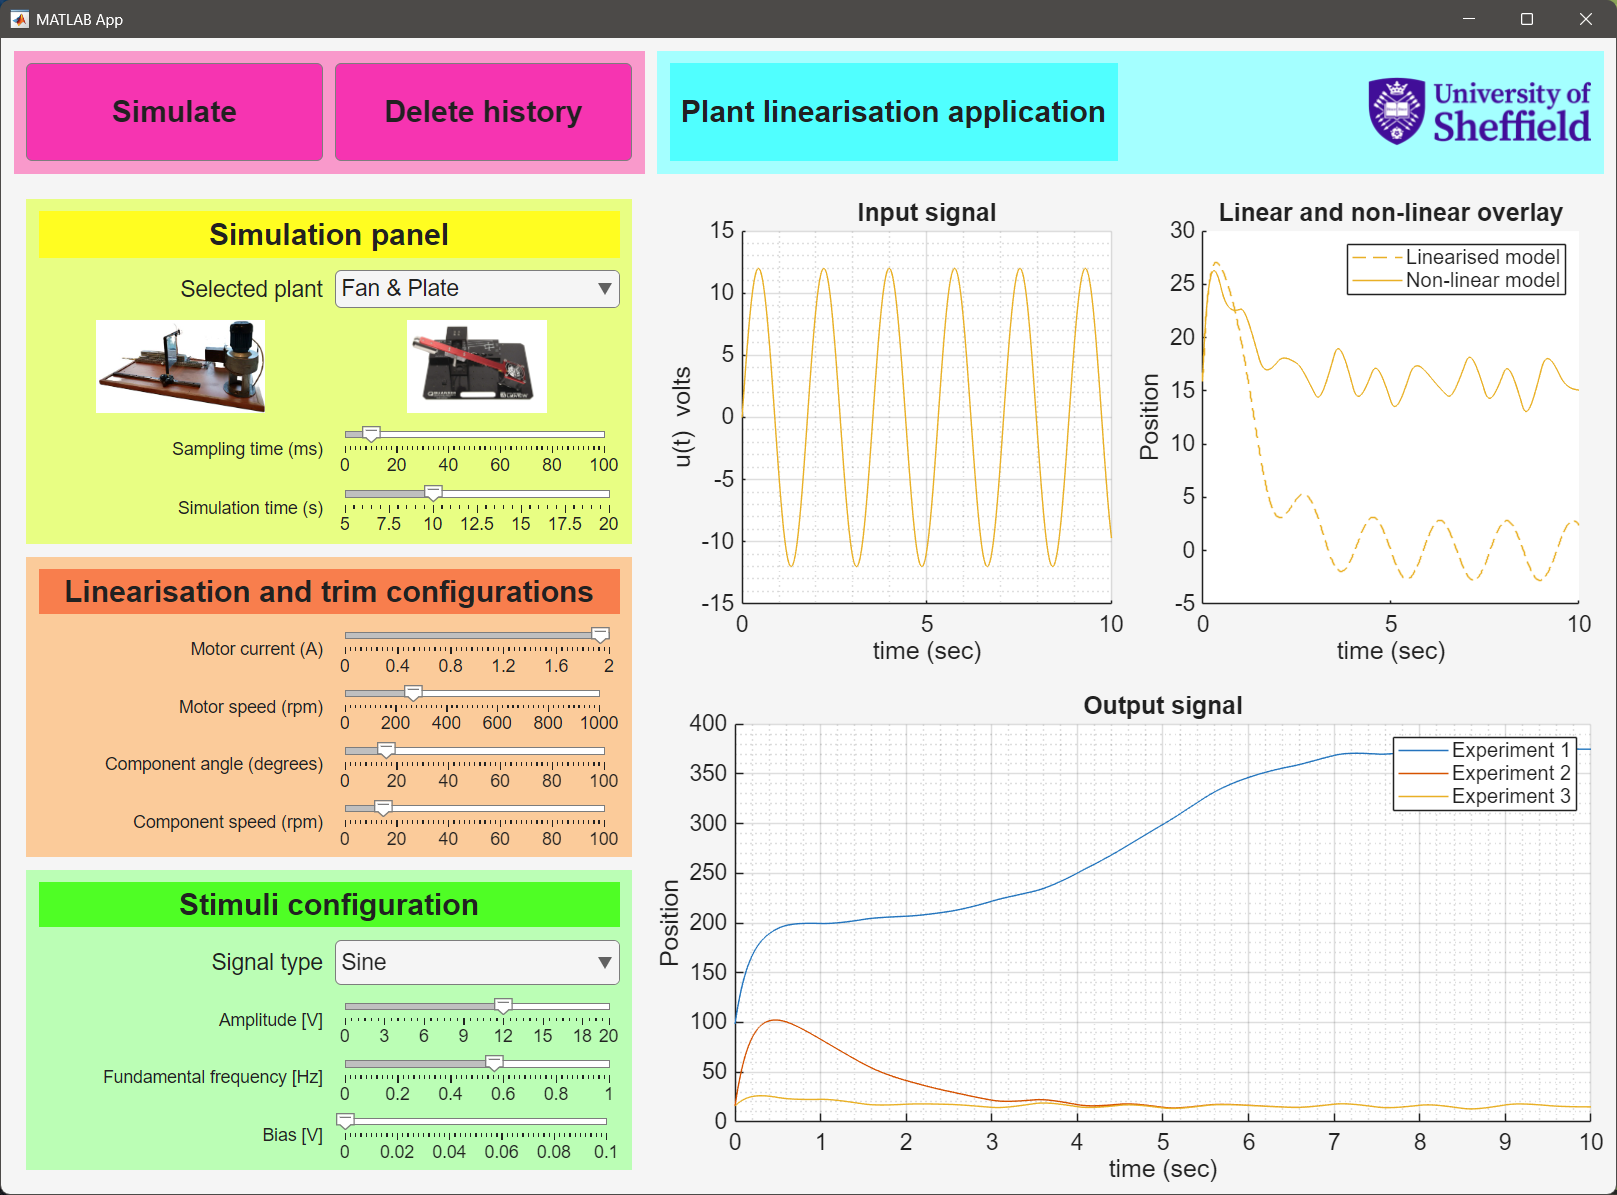

Figure 3 Screen capture from the virtual laboratory ***linearisation_Benchmark_control101 .mlapp***

## 5 Establishing Computer Controlled Systems

This section is for completeness and provides links to other resources which are part of the same group of work within Computer Controlled Systems Virtual Lab. 

A typical continous feedback control system structure is shown in Figure 4.

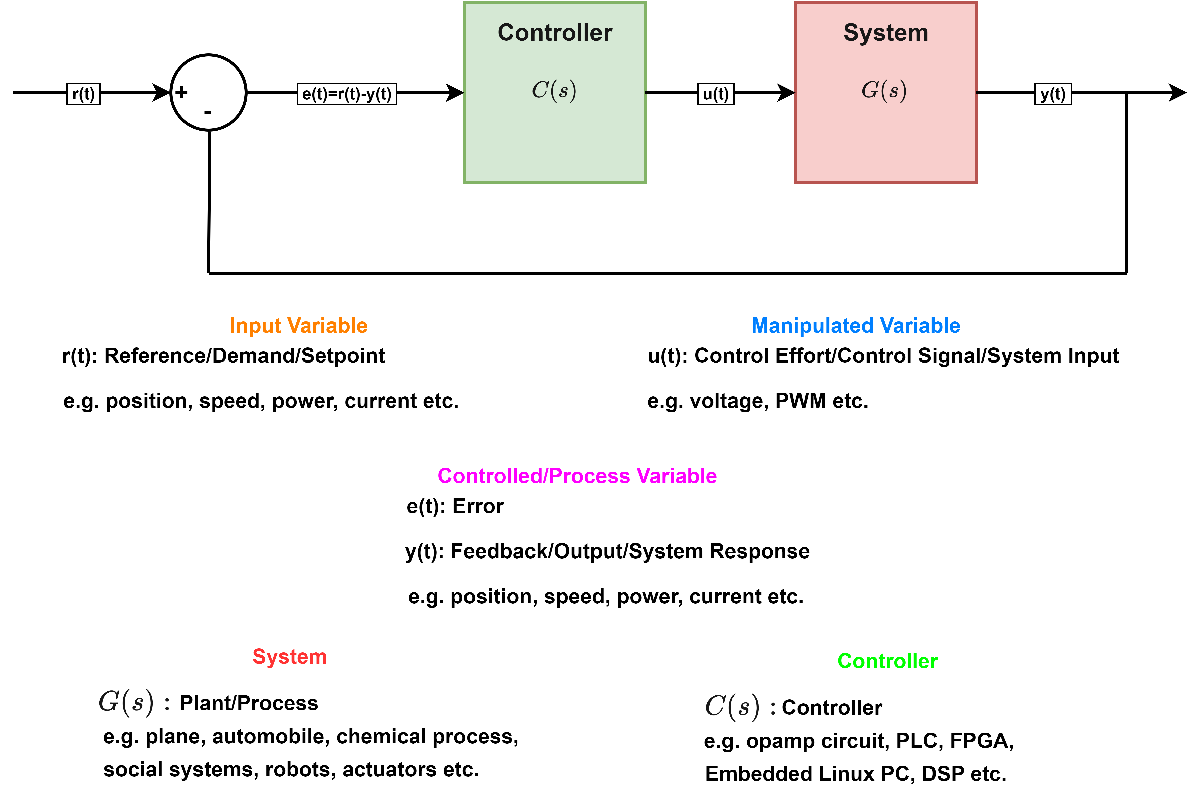

Figure 4. Continous Feedback Control Systems

When a microprocessor/digital processing unit is considered for controller implementation, computer controlled systems is needed to establish. In computer controlled systems, in addition to control units, some interface units that enables communication of continous-time world of the system to be controlled, and discrete-time world of digital controller. These units are A/D (Analog to Digital) converters and D/A (Digital to Analog) converters that accomplish Quantizations, Sampling and Holding Operations. See block diagram in Figure 4 for computer controlled systems. A number of other toolbox files are available to help students investigate this scenario; shortcuts to these are available under the relevant toolbox sampling tab. All the virtual laboratories are supported by livescripts which open automatically when the laboratory is used.

- To investigate affect of quantization (resolution) and sampling operation explained in details in the virtual laboratory **Analog_to_Digital_Converter_Application_control101.mlapp, c*****losed_Loop_Under_Sampling_control101.mlapp,               Continuous_and_Discrete_time_Mapping_control101.mlapp, Signal_Types_in_Computer_Controlled_Systems_Application.mlapp***    

- To investigate the potential to regain information in the continuous time signal from the discretised one: **Digital_to_Analog_Converter_Application_control101.mlapp.** 

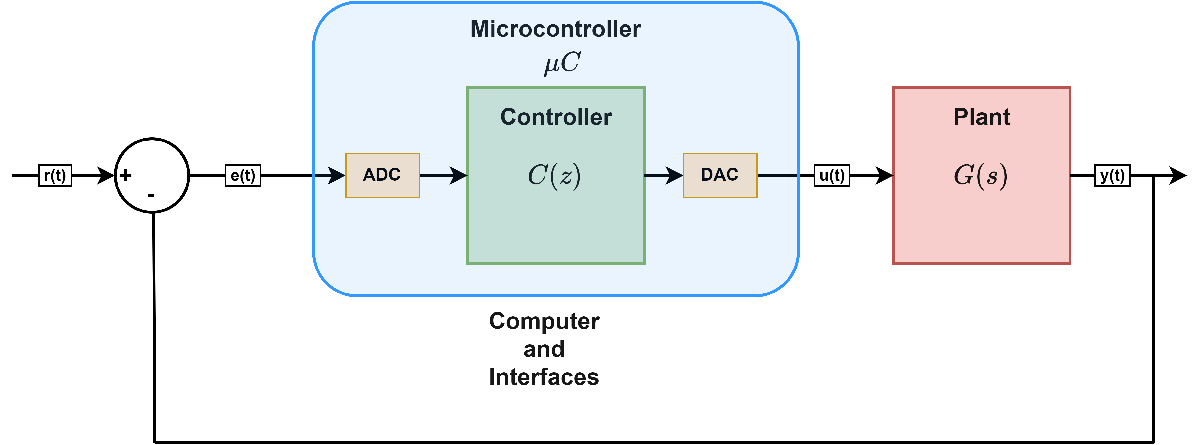

Figure 4. Computer Controlled Systems

Different types of signals exist in above diagram. See the live script **Signal_Types_in_Computer_Controlled_Systems_Application_control101.mlx**.

References:

[1] Wittenmark, Björn, Karl-Erik Årzén, and Karl Johan Åström. "Computer control: An overview." *IFAC Professional Brief* , 2002.

[2] Goren-Sumer, Leyla, Bilgisayar Kontrollü Sistemler ders slaytları (Lecture slides of Computer-Controlled Systems), 2021.

[3] Ogata, Katsuhiko. *Discrete-time control systems*. Prentice-Hall, Inc., 1995.

Note: Some assistance from ChatGPT was used in developing the MATLAB codes of examples.